The first 3 files are for Wesley, the next 3 are for Elvis, and the last 3 are for Melissa. At first we had 6 balls to hit per file, but we later had only 5. All swings were forehand. Data was recorded at 100Hz.

Because there is rotation, it is important to have the orientation data so we can translate back to the global coordinate system.

First, load in all the data files and pick out the individual hits.

There is a signficant amount of extra data at the start because we had to fit the phone into the armband and setup each time. We can remove this off the bat to make it easier to identify the individual hits.

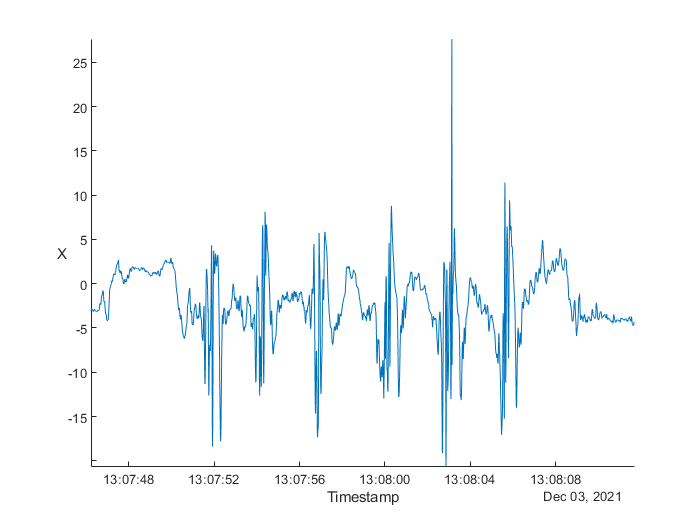

clear;
load data\data4.mat
% plot overything so we can get a sense of what our data looks like
% once we figure it out for one sample, we can trim the others and repeat
%TODO: label
% if we have time it would be cool to ffmpeg the video into frames and then
% plot on top
stackedplot(Acceleration(:,"X"))

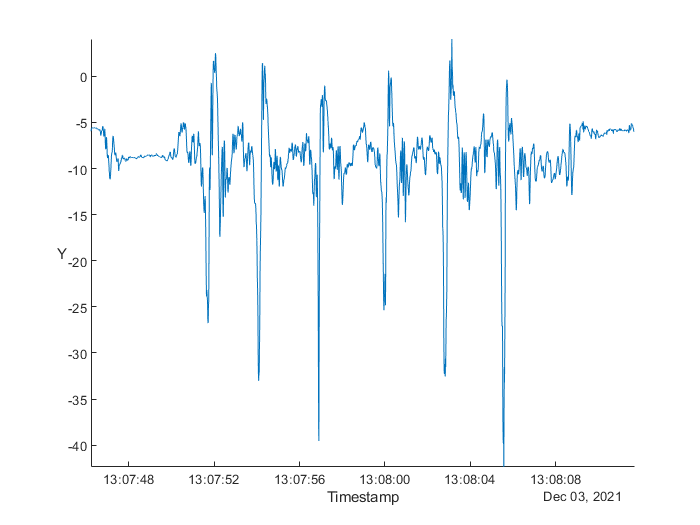

stackedplot(Acceleration(:,"Y"))

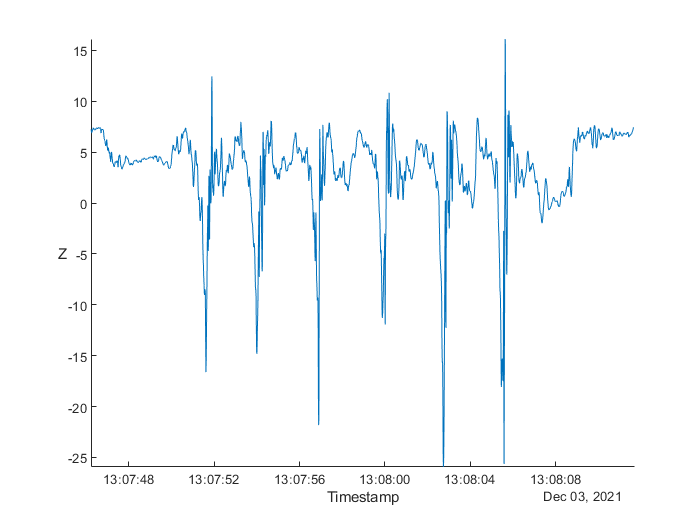

stackedplot(Acceleration(:,"Z"))

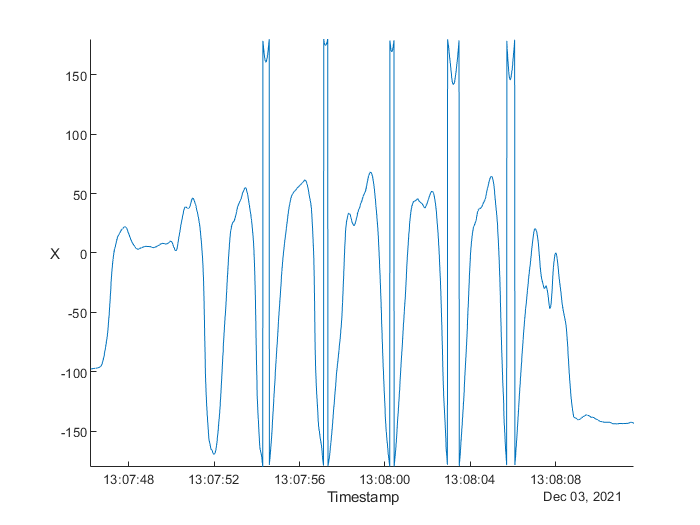

stackedplot(Orientation(:,"X"))

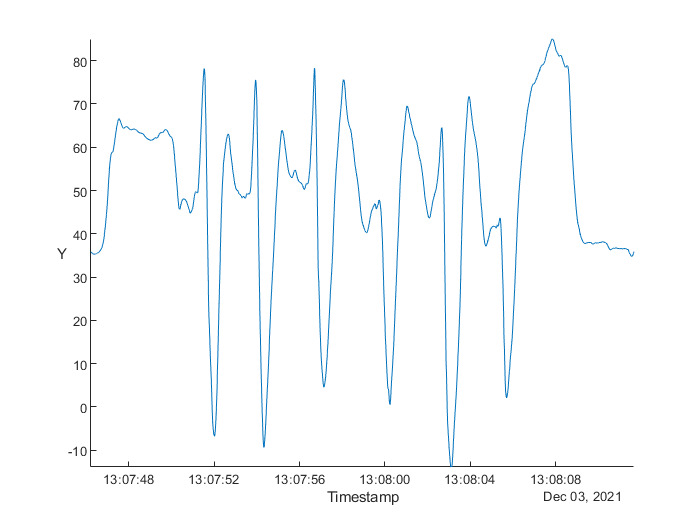

stackedplot(Orientation(:,"Y"))

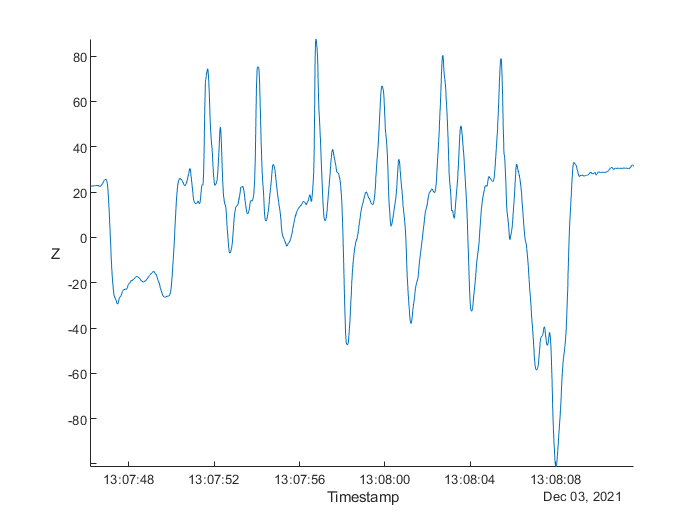

ans =    -2.9736   -5.9364    7.2425
   -3.0998   -5.8278    7.2078
   -2.8356   -5.6192    7.0529
   -2.7296   -5.6636    6.9051
   -2.8496   -5.6394    6.9143
   -3.0180   -5.5853    7.0165
   -2.9808   -5.5743    7.0496
   -2.8809   -5.5888    7.1208
   -2.9385   -5.5957    7.1904
   -3.0324   -5.6225    7.2741


ans = 2560×1 datetime array
   03-Dec-2021 13:07:46.225
   03-Dec-2021 13:07:46.235
   03-Dec-2021 13:07:46.245
   03-Dec-2021 13:07:46.255
   03-Dec-2021 13:07:46.265
   03-Dec-2021 13:07:46.275
   03-Dec-2021 13:07:46.285
   03-Dec-2021 13:07:46.295
   03-Dec-2021 13:07:46.305
   03-Dec-2021 13:07:46.315
   03-Dec-2021 13:07:46.325
   03-Dec-2021 13:07:46.334
   03-Dec-2021 13:07:46.345
   03-Dec-2021 13:07:46.355
   03-Dec-2021 13:07:46.365
   03-Dec-2021 13:07:46.375
   03-Dec-2021 13:07:46.385
   03-Dec-2021 13:07:46.394
   03-Dec-2021 13:07:46.404
   03-Dec-2021 13:07:46.414
   03-Dec-2021 13:07:46.424
   03-Dec-2021 13:07:46.434
   03-Dec-2021 13:07:46.444
   03-Dec-2021 13:07:46.454
   03-Dec-2021 13:07:46.464
   03-Dec-2021 13:07:46.474
   03-Dec-2021 13:07:46.484
   03-Dec-2021 13:07:46.494
   03-Dec-2021 13:07:46.504
   03-Dec-2021 13:07:46.514


orienation_matrix =   -97.4381   35.8373   22.7327
  -97.4227   35.7837   22.7045
  -97.3960   35.7094   22.6787
  -97.3587   35.6381   22.6605
  -97.3250   35.5857   22.6556
  -97.2929   35.5320   22.6522
  -97.2593   35.4837   22.6519
  -97.2295   35.4507   22.6658
  -97.2095   35.4188   22.7002
  -97.1859   35.3825   22.7274


stackedplot(Orientation(:,"Z"))

% visualize the orientation over time
figure();
% current position
x = 0; y = 0; z = 0;
% plot the orientation vectors
BASIS = [ 
    1 0 0;
    0 1 0;
    0 0 1;
];
points = height(Acceleration);
position = [x, y, z];
for idx=1:3:points % speedup to keep animation relatime (remove later!)
    R = rot(orienation_matrix(idx, :));
    V = R * BASIS;
    hold on;
    quiver3(position(1), position(2), position(3), V(1,1), V(1,2), V(1,3), 0, 'r');
    quiver3(position(1), position(2), position(3), V(2,1), V(2,2), V(2,3), 0, 'b');
    quiver3(position(1), position(2), position(3), V(3,1), V(3,2), V(3,3), 0, 'g');
    hold off;
    axis equal;
    xlim([-1, 1]);
    ylim([-1, 1]);
    zlim([-1, 1]);
    drawnow limitrate; %run at 20fps, remove this for exporting to video
    clf;
end

% FIRST project onto the global coordinate system
Accel = normalize_acceleration(Acceleration, Orientation);
Acceleration;
% integrate for velocity
% integrate again for position

%TODO: visualize the position and velocity and acceleration vectors


% maybe looking at upwards acceleration would allow us to evaluate spin?
% can probably get angle at impact
% maybe could get some sample data to show we can score low for having a
% really bad angle

% https://www.mathworks.com/matlabcentral/fileexchange/23629-export_fig
% might work for saving as a transparent overlay for video
% otherwise can just live with the white background

function R = rot(angle)
    R = rotz(angle(3)) * roty(angle(2)) * rotx(angle(1));
end

% take the acceleration and orientation data and transform the axis to the
% global system
function A = normalize_acceleration(accel, orient)
    % unfortunately because orientation is changing we have to transform
    % row by row instead of just using a single matrix multiplication
    vectors = accel.Variables;
    orientation_vectors = orient.Variables;
    for i=1:height(accel)
        vector = vectors(i, :);
        % now that we don't need it anymore overwrite it
        vectors(i, :) = vector * rot(orientation_vectors(i, :));
    end
    t = accel.Timestamp; % get the times for creating a new timetable
    A = timetable(t, vectors(:, 1), vectors(:, 2), vectors(:, 3), 'VariableNames',{'X','Y', 'Z'});
end